Definmos el sistema en simbólico.

syms x1 x2 real
f(1, 1) = x1*(x1^2 + x2^2 -1) - x2;
f(2, 1) = x1 + x2*(x1^2+x2^2-1)

$$f = \left(\begin{array}{c} x_{1}\,\left({x_{1}}^{2}+{x_{2}}^{2}-1\right)-x_{2}\\ x_{1}+x_{2}\,\left({x_{1}}^{2}+{x_{2}}^{2}-1\right) \end{array}\right)$$

Sacamos el jacobiano y los puntos de equilibrio.

J = jacobian(f, [x1 x2]);
[x1eq, x2eq] = solve(f, [x1 x2]);
% si existen varios puntos de equilibrio
Xeq = [x1eq, x2eq]

$$Xeq = \left(\begin{array}{cc} 0 & 0 \end{array}\right)$$

Sustituimos los puntos de equilbrio en el jacobiano para identificar su estabilidad.

for i =1:size(Xeq, 1)
    %sustituimos la solucion en la expresion del Jacobiano
    Jeq = subs(J, {x1,x2}, Xeq(i,:))
    E = eig(Je)
end

$$Jeq = \left(\begin{array}{cc} -1 & -1\\ 1 & -1 \end{array}\right)$$

$$E = \left(\begin{array}{c} -1-\mathrm{i}\\ -1+\mathrm{i} \end{array}\right)$$

Análisis de estabilidad por Lyapunov.

P = lyap(Je,eye(2))

P =     0.5000         0
         0    0.5000


Vsym = [x1, x2]*P*[x1; x2]

$$Vsym = \frac{{x_{1}}^{2}}{2}+\frac{{x_{2}}^{2}}{2}$$

grvSym = gradient(Vsym);
dotvSym = grvSym'*f;
dotvSym = simplify(dotvSym)

$$dotvSym = {x_{1}}^{4}+2\,{x_{1}}^{2}\,{x_{2}}^{2}-{x_{1}}^{2}+{x_{2}}^{4}-{x_{2}}^{2}$$

V = matlabFunction(Vsym)

V = function_handle with value:
    @(x1,x2)x1.^2./2.0+x2.^2./2.0


dotv = matlabFunction(dotvSym)

dotv = function_handle with value:
    @(x1,x2)x1.^2.*x2.^2.*2.0-x1.^2-x2.^2+x1.^4+x2.^4


Representación de $V$.

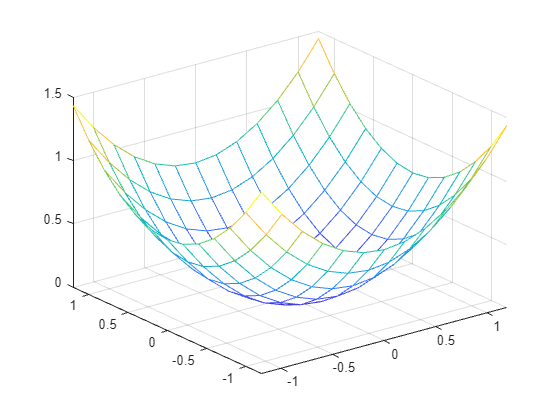

x1Lin = -1.2:0.2:1.2;
x2Lin = -1.2:0.2:1.2;
[x1Mesh, x2Mesh] = meshgrid(x1Lin, x2Lin);
figure
mesh(x1Mesh, x2Mesh, V(x1Mesh, x2Mesh))

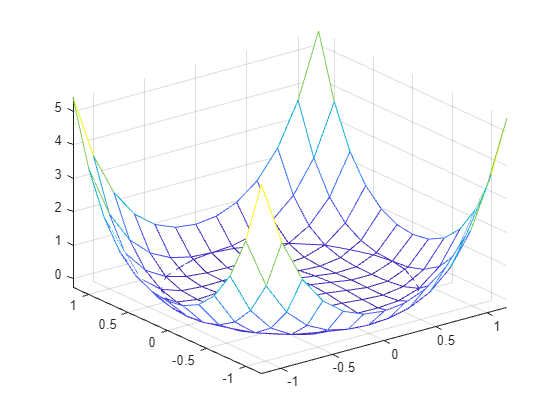

figure
mesh(x1Mesh, x2Mesh, dotv(x1Mesh, x2Mesh))
hold on
contour3(x1Mesh, x2Mesh, dotv(x1Mesh, x2Mesh), [0, 0])

Diagrama de fases del sistema.

fNum = matlabFunction(f)

fNum = function_handle with value:
    @(x1,x2)[-x2+x1.*(x1.^2+x2.^2-1.0);x1+x2.*(x1.^2+x2.^2-1.0)]


fNumT = @(t, x) fNum(x(1,1), x(2,1))

fNumT = function_handle with value:
    @(t,x)fNum(x(1,1),x(2,1))


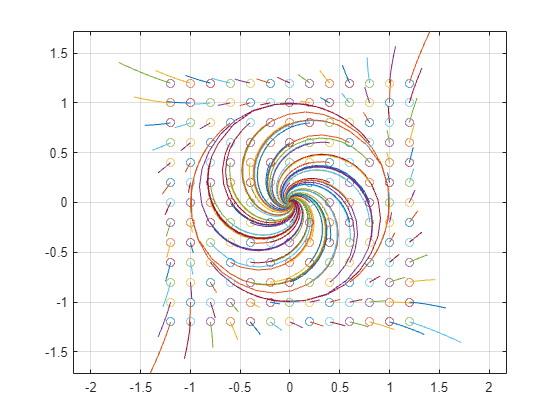

tf = 1;
odeOpts = odeset(MaxStep='auto');
figure
for i = 1:length(x1Lin)
     for j = 1:length(x2Lin)
         % al haber una frontera de estabilidad
         if x1Lin(i)^2 + x2Lin(j)^2 >= 1
             tf = 0.1;
         else
             tf = 10;
         end
         [t,x] = ode45(@(t,x)fNumT(t,x),[0,tf],[x1Lin(i);x2Lin(j)]);
         plot(x1Lin(i),x2Lin(j),'o')
         hold on
         plot(x(:,1),x(:,2))
         
     end
end
axis equal
grid on